load('/home/dclab2/pcadata.mat');
for m = 1:18
     patchdata{1,m} = zeros(89,96,81);
     for i = 1:12
       
        patchdata{1,m} = patchdata{1,m}+All_data_prepatch{i,m}(1:89,:,:)-mean(All_data_prepatch{1,m}(1:89,:,1:20),3);
    end
end

load('/home/dclab2/Ensemble coding/data/SNR.mat');
% 选择前 30 个线圈
[~, coilidx] = sort(coilSNR, 'descend');
coilselect = coilidx(1:24);
All_data  = {All_data_preEC,All_data_preEC0,All_data_preSC,All_data_prepatch,patchdata};

## 主成分提取

data = [All_data{2}{1,9}(1:89,coilselect,:);All_data{5}{1,9}(1:89,coilselect,:)];
% 沿时间维度（第3维）计算滑动窗口总和

window_counts = movsum(data, 5, 3, 'Endpoints', 'discard');
datanew = squeeze(data(1,:,:));
for num = 2:size(data,3)
    datanew = cat(2,datanew,squeeze(data(num,:,:)));
end
datanew = (datanew-min(datanew(:)))/(max(datanew(:))-min(datanew(:)));
% 验证维度
assert(size(window_counts,3) == 77, '维度错误');
[coeff_pca, score_pca, ~, ~, explained] = pca(datanew');

for i =1:size(data,3)
    % trial,time,pcs
    pcaresult{2}(i,:,:) = score_pca(((i-1)*81+1):i*81,:);
end


color1 = [0.73, 0.58, 0.24;   % 条件1颜色（琥珀金）
          0.18, 0.48, 0.43];  % 条件2颜色（松石绿）
fill_color1 = [0.95, 0.89, 0.71;  % 条件1填充色
              0.70, 0.85, 0.81];   % 条件2填充色
labelname = {'10°','90°'}
figure;
for i = 1:5
    subplot(5,1,i);
    hold on;
    
    % ===== 绘制两个条件的数据 =====
    for condition = 1:2
        data1 = squeeze(pcaresult{condition}(:,:,i));
        mean_values = mean(data1, 1);
        time_points = 1:size(data1, 2);
        
        % 绘制均值线（设置图例标签）
        h(condition) = plot(time_points, mean_values, 'LineWidth', 2, ...
                           'Color', color1(condition,:), ...
                           'DisplayName', [labelname{condition}]);
        
        % 计算并填充标准误（不显示在图例中）
        std_dev = std(data1, 0, 1);
        se_values = std_dev / sqrt(size(data1,1));
        fill([time_points, fliplr(time_points)], ...
             [mean_values+se_values, fliplr(mean_values-se_values)], ...
             fill_color1(condition,:), 'EdgeColor', 'none', ...
             'FaceAlpha', 0.3, 'HandleVisibility', 'off');
    end
    
    % ===== 添加灰色块 =====
    y_limits = ylim;
    fill([21,40,40,21], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], ...
         [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none', ...
         'HandleVisibility', 'off');
    
    hold off;
    
    % ===== 仅在第一个子图显示图例 =====
    if i == 1
        legend(h, 'Location', 'best'); % 显示图例
    else
        legend off; % 隐藏其他子图例
    end
    
    % ===== 坐标轴标签 =====
    xlabel('Time');
%     xticks(0:10:80)
%     xticklabels(-40:20:120);
    ylabel(['PC ', num2str(i)]);
    
end

## 计算CD变化

EC0_10 = All_data{1,5}{1,9}(1:89,coilselect,:);
EC0_90 = All_data{1,1}{1,9}(1:89,coilselect,:);

EC0_10 = rescale(EC0_10,0,1);
EC0_90 = rescale(EC0_90,0,1);
% Matlab版本
% 提取基线期数据
baseline_right = EC0_10(:, :, 1:20);  % 89×30×20
baseline_left = EC0_90(:, :, 1:20);

% 合并数据
baseline_all = cat(1, baseline_right, baseline_left);  % 178×30×20

% 计算均值和标准差
baseline_mean = mean(mean(baseline_all, 1), 3);  % 1×30
baseline_std = std(reshape(baseline_all, [], 30), 0, 1);  % 1×30
for t = 21:81
% Matlab版本
task_right = EC0_10(:, :, t);  % 89×30×21
task_left = EC0_90(:, :, t);

% 计算平均（跨试次和时间点）
mean_right = mean(mean(task_right, 1), 3);  % 1×30
mean_left = mean(mean(task_left, 1), 3);    % 1×30

% Matlab版本
x_right_corrected = (mean_right - baseline_mean) ./ baseline_std;
x_left_corrected = (mean_left - baseline_mean) ./ baseline_std;
% Matlab版本
v = x_right_corrected - x_left_corrected;  % 1×30
% Matlab版本
% 方差归一化
variance_sum_sqrt = sqrt(sum(baseline_std .^ 2));
v_normalized = v / variance_sum_sqrt;

% L1归一化
v_final = v_normalized / sum(abs(v_normalized));

% 最终CD向量
CD = v_final;  % 1×30

% Matlab示例：解码验证
% 假设已计算每个试次的投影值
projection_right = mean(task_right,3) * CD';  % task_right_avg: 89×30
projection_left = mean(task_left,3) * CD';    % task_left_avg: 89×30

% 计算AUC
labels = [ones(89,1); zeros(89,1)];
scores(:,t) = [projection_right; projection_left];
[~,~,~,auc] = perfcurve(labels, scores(:,t), 1);
fprintf('AUC: %.2f\n', auc);
end


IEM

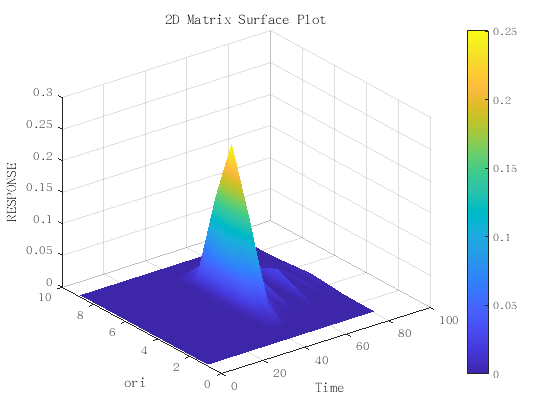

%clearvars -except All_data coilselect
orientations = 10:20:170;
n_channels = 9;  % 假设9个方向通道

CC = zeros(n_channels, n_channels,40);  % 每个试次对应一个方向通道

for trial = 1:40
    for i = 1:n_channels
        tuning = cosd(orientations(i) - orientations).^8;  % 半正弦函数八次方
        CC(:, i,trial) = tuning / max(tuning);  % 归一化
    end
end

for ori = 1:9
    EC0train(ori,:,:,:) = All_data_preEC0{1,ori*2-1}(1:40,coilselect,:);
    EC0test(ori,:,:,:) = All_data_preEC0{1,ori*2-1}(41:80,coilselect,:);
    ECtest(ori,:,:,:) = All_data_preEC{1,ori*2-1}(1:40,coilselect,:);
end
EC0train = rescale(EC0train,0,1);
EC0test =rescale(EC0test,0,1);
ECtest = rescale(ECtest,0,1);

for t = 1:81
for ori =1:9
    homo_datatrain = squeeze(EC0train(ori,:,:,t));
    homo_datatest = squeeze(EC0test(ori,:,:,t));
    hes_datatest = squeeze(ECtest(ori,:,:,t));

B1 = homo_datatrain';  

C1 = squeeze(CC(ori,:,:));

W = B1 * C1' *pinv(C1 * C1');

%训练ori，time，trial，偏差角度
EC0res(ori,t,:,:) = homo_datatest * W;
EC0Patchres(ori,t,:,:) = hes_datatest * W;
end
end


test1 = squeeze(EC0res(5,:,1,:))';
test2 = squeeze(EC0res(5,:,1,:))';
[X, Y] = meshgrid(1:size(test1,2), 1:size(test1,1));  % 默认坐标
% 或自定义坐标范围：
% [X, Y] = meshgrid(linspace(-5,5,size(Z,2)), linspace(-3,3,size(Z,1)));
figure;
surf(X, Y, test1);  % 或 mesh(X, Y, Z)
title('2D Matrix Surface Plot');
xlabel('Time');
ylabel('ori');
zlabel('RESPONSE');
colorbar;       % 显示颜色条
shading interp; % 平滑着色（可选）
colormap parula;% 设置颜色映射（可选）

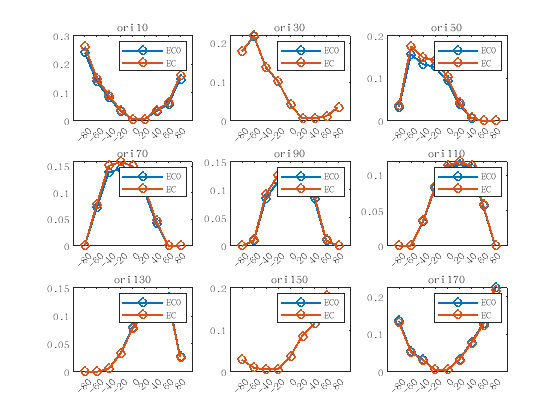


figure;
for ori = 1:9
    subplot(3,3,ori)
plot(smooth(squeeze(mean(EC0res(ori,43,:,:),3))),"Marker","o",'LineWidth',1.5)
hold on
plot(smooth(squeeze(mean(EC0Patchres(ori,43,:,:),3))),"Marker","o",'LineWidth',1.5)

legend('EC0','EC')
hold off
subtitle(sprintf('ori%d',ori*20-10));
xticks(1:9)
xticklabels(-80:20:80);
en